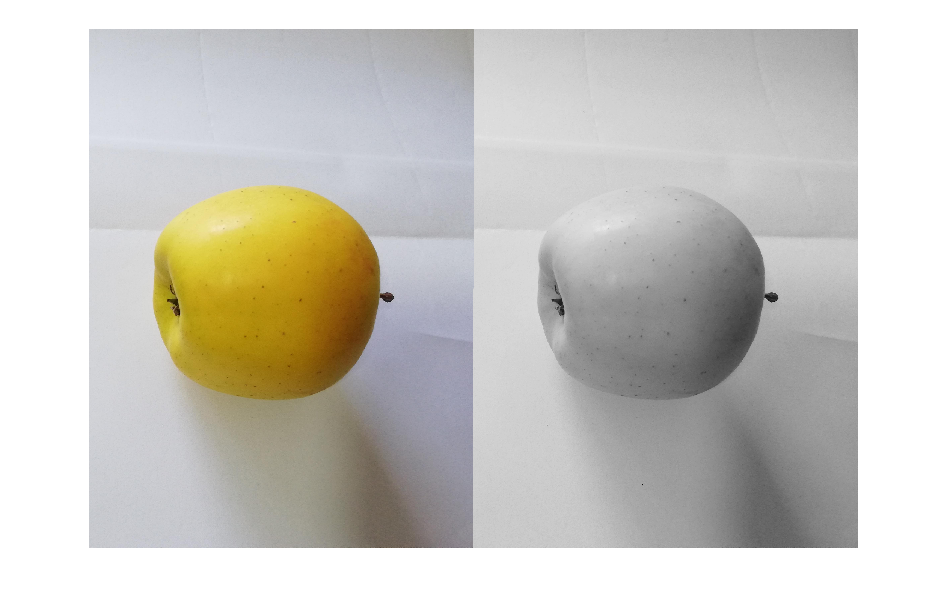

im1=imread('F01.jpg');
im1_escalagrises = ImagenGrises(im1);
imagen=[im1 im1_escalagrises];
imshow(imagen)


%Calculo luminancia max  min
maximo=im2double(max(max(im1_escalagrises)));
minimo=im2double(min(min(im1_escalagrises)));


im1_double = im2double(im1_escalagrises);       % Paso a double 
im1_double = im2double(im1);
fruta_contrastada = ((im1_double - minimo)./(maximo-minimo))*1 + 0;%hai que pasar a double, sino da error
img_final =  [im1_double fruta_contrastada];  % Concateno
imshow(img_final)




#### FUNCIÓN PARA PASAR A ESCALA DE GRISES

function imbn = ImagenGrises(imc)
    R = imc(:,:,1);
    G = imc(:,:,2);
    B = imc(:,:,3);
    
    Y = 0.3*R+0.59*G+0.11*B;    % Calculo Y
    % Para que esté en escala de grises --> Y = R = G = B
    imbn(:,:,1) = Y;    % R = Y
    imbn(:,:,2) = Y;    % G = Y
    imbn(:,:,3) = Y;    % B = Y
end